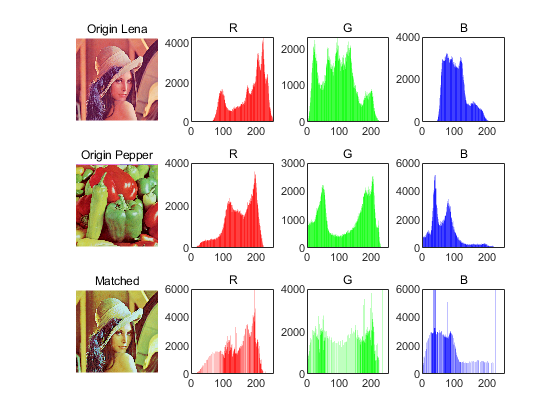

clf;
clear;

lena = imread("../images/lena_color.tif");
pepper = imread("../images/PeppersRGB.tif");
[M,N,C]=size(lena);
[m,n,c]=size(pepper);
%imshow(lena);
%imshow(pepper);

% show Lena
figure;
subplot(3,4,1)
imshow(lena);title('Origin Lena');
L1=lena(:,:,1);
L2=lena(:,:,2);
L3=lena(:,:,3);
L1_hist = my_hist(L1);
L2_hist = my_hist(L2);
L3_hist = my_hist(L3);
subplot(3,4,2);
bar(1:256,L1_hist,'r');title('R');
subplot(3,4,3);
bar(1:256,L2_hist,'g');title('G');
subplot(3,4,4);
bar(1:256,L3_hist,'b');title('B');

% show pepper
subplot(3,4,5)
imshow(pepper);title('Origin Pepper');
P1 = pepper(:,:,1);
P2 = pepper(:,:,2);
P3 = pepper(:,:,3);
P1_hist = my_hist(P1);
P2_hist = my_hist(P2);
P3_hist = my_hist(P3);
subplot(3,4,6);
bar(1:256,P1_hist,'r');title('R');
subplot(3,4,7);
bar(1:256,P2_hist,'g');title('G');
subplot(3,4,8);
bar(1:256,P3_hist,'b');title('B');
%==============================================================
% HE function
T_L1 = zeros(1,256);
T_L2 = zeros(1,256);
T_L3 = zeros(1,256);
T_P1 = zeros(1,256);
T_P2 = zeros(1,256);
T_P3 = zeros(1,256);

for k = 1:256
    if k == 1
        T_L1(k) = 255*L1_hist(k)/M/N;
        T_L2(k) = 255*L2_hist(k)/M/N;
        T_L3(k) = 255*L3_hist(k)/M/N;
        T_P1(k) = 255*P1_hist(k)/m/n;
        T_P2(k) = 255*P2_hist(k)/m/n;
        T_P3(k) = 255*P3_hist(k)/m/n;
    else
        T_L1(k) = T_L1(k-1) + 255*L1_hist(k)/M/N;
        T_L2(k) = T_L2(k-1) + 255*L2_hist(k)/M/N;
        T_L3(k) = T_L3(k-1) + 255*L3_hist(k)/M/N;
        T_P1(k) = T_P1(k-1) + 255*P1_hist(k)/m/n;
        T_P2(k) = T_P2(k-1) + 255*P2_hist(k)/m/n;
        T_P3(k) = T_P3(k-1) + 255*P3_hist(k)/m/n;
    end
end

% finding minimum points
idx1 = zeros(1,256);
idx2 = zeros(1,256);
idx3 = zeros(1,256);
for i=1:256
    [min1,idx1(i)]=min(abs(T_P1-T_L1(i)));
    [min2,idx2(i)]=min(abs(T_P2-T_L2(i)));
    [min3,idx3(i)]=min(abs(T_P3-T_L3(i)));
end

% matching
match1=zeros(m,n);
match2=zeros(m,n);
match3=zeros(m,n);
for i=1:m
   for j=1:n
      match1(i,j)=idx1(L1(i,j)+1)-1;
      match2(i,j)=idx2(L2(i,j)+1)-1;
      match3(i,j)=idx3(L3(i,j)+1)-1;
   end
end

lena(:,:,1)=uint8(match1);
lena(:,:,2)=uint8(match2);
lena(:,:,3)=uint8(match3);
% lena(:,:,1)=histeq(lena(:,:,1),P1_hist); % check
% lena(:,:,2)=histeq(lena(:,:,2),P2_hist);
% lena(:,:,3)=histeq(lena(:,:,3),P3_hist);
subplot(3,4,9);
imshow(lena);title('Matched');
subplot(3,4,10);
bar(1:256,my_hist(lena(:,:,1)),'r');title('R');
ylim([0,6000]);
subplot(3,4,11);
bar(1:256,my_hist(lena(:,:,2)),'g');title('G');
ylim([0,4000]);
subplot(3,4,12);
bar(1:256,my_hist(lena(:,:,3)),'b');title('B');
ylim([0,6000]);

function output = my_hist(input)
[M,N] = size(input);
output = zeros(1,256);

for k = 1:256
    for m = 1:M
        for n = 1:N
            output(k) = output(k) + (input(m,n) == k);
        end
    end
end
end